## **Introducción.**

Los conjuntos son una colección bien definida de elementos y gracias a la teoría clásica de conjuntos, podemos agruparlos de acuerdo a la pertenencia o no a estas agrupaciones, surge, entonces naturalmente la idea de etiquetar elementos con los estigmas "pertenece" o "no pertenece", "si ó "no",si es parte de un todo o de nada, matemáticamente si es 1 ó 0.

Sin embargo, debido a la necesidad de dejar la restricción entre valores extremos como 1 y 0, surge la lógica difusa y con ella una nueva teoría de conjuntos, donde se es mas flexible respecto a los valores que pueden tomar ciertos elementos de acuerdo a la pertenencia o no a un grupo o clasificación específico, a lo que se le llamó grado de pertenencia o membresía; así estos valores pueden tomar cualquier cantidad entre el intervalo [0,1].

Así un conjunto difuso asocia a cada elemento de un universo un grado de pertenencia, y, derivado de esta relación podemos definir a un conjunto difuso como una función o correspondencia.

Podemos decir que mientras más cercano a 1 sea el grado de membresía, más pertenenciente es ese elemento al conjunto en cuestión, y entre más cercano a cero, se alejaba de pertenencer, donde el cero es la nula pertenencia.

Las funciones de pertenencia pueden emplearse de dos formas diferentes: 

- Para estimar grados de pertenencia a un conjunto 

-  Para expresar posibilidades en una situación en la que se dispone de información incompleta

Es de un importante uso este tipo de funciones para la resolución de algunos problemas, puesto que muchas veces es dificil definir elementos con una extrema rigidez como lo sería con conjuntos clásicos, por ejemplo el modelado del pensamiento humano, en donde es necesario buscar y plasmar un proceso de razonamiento gradual, donde existen demasiadas variables que no pueden ser rigurosamente definidas, es entonces donde surge la necesidad de definir algunos conceptos importantes como como "variable lingüística", "universo", "valor lingüístico", etc ya que en el lenguaje casual, usamos expresiones como "mas o menos", "casi", "muy","muy poco", entre otras. 

### Problema 1.

### Función smf.

Devuelve valores de pertenencia difusos calculados utilizando la función de pertenencia en forma de S basada en spline dada por:


$$f(x;a,b) = \begin{cases}
0 &\text{ $ x \le a $}\\
2(\frac {x-a}{b-a})^2 &\text{ $a \le x\le \frac {a+b}{2}$}\\
1-2(\frac {x-b}{b-a})^2 &\text{ $\frac {a+b}{2} \le x\le b$}\\
1 &\text{ $ x \ge b $}\\
\end{cases}$$


### Función psigmf.

Esta función calcula valores de pertenencia difusos utilizando el producto de dos funciones de pertenencia sigmoidea.


$$f\left(x;a_k ,c_k \right)=\frac{1}{1+e^{-a_k \left(x-c_k \right)} }$$


**Problema 3 **

Repite el problema anterior pero para conjuntos difusos en tiempo discreto.  

Prueba esta función con los conjuntos difusos (A, B) de la imagen 5 (OperDif5). de las notas *NO2. Operaciones difusas que se encuentran en* la página del curso.

Se espera esta sección dos llamadas a la función con las dos gráficas respectivas. 

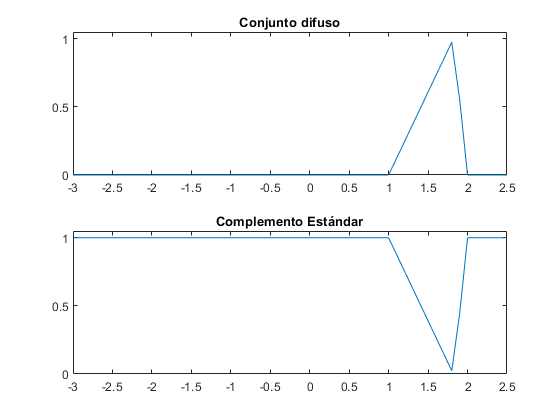

estandar =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.1220    0.2439    0.3659    0.4878    0.6098    0.7317    0.8537    0.9756    0.5556


A = [1/1.0 0.75/1.5 0.3/2.0 0.15/2.6 + 0/3.0]
B = [1/1.0 0.6/1.5 0.2/2.0 0.1/2.5 0/3.0]
% Llamar a funcion de problema dos y pasar parametros.

**Problema 4**

Elabora una función que reciba el conjunto dominio x y el rango A de un conjunto difuso. Un parámetro adicional que indique el tipo de complemento que se quiere hacer (estándar, Sugeno, Yager). La función debe regresar el rango de valores del conjunto resultante C. Además de imprimir una figura (2 por 1) donde se muestren las grafica de los dos conjunto involucrados.

Prueba esta función con el inciso a) de la imagen 4 (OperDif4). de las notas *NO2. Operaciones difusas que se encuentran en* la página del curso. Para esto:

- Reporta los tres tipos de complementos (si no puedes implentar esto es una solo función crea tres funciones de complemento difuso)

- Combina las herramientas que ya tienes desarrolladas (de ser posible) para mostrar una gráfica con los tres tipos de complementos o desarrolla esta gráfica sin utilizar tus herramientas

En esta sección se espera tres llamadas a la función y un código para generar la cuarta gráfica. 

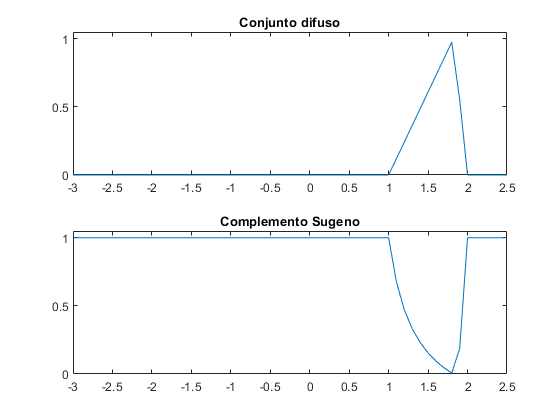

sugeno =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.1220    0.2439    0.3659    0.4878    0.6098    0.7317    0.8537    0.9756    0.5556


dominio = -3:0.1:2.5;

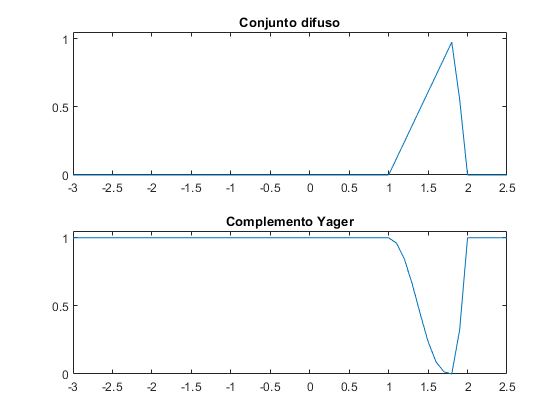

yager =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.1220    0.2439    0.3659    0.4878    0.6098    0.7317    0.8537    0.9756    0.5556


rango = [1 1.82 2];

estandar = problema4(dominio, rango, 'Estandar')
sugeno = problema4(dominio, rango, 'Sugeno')
yager = problema4(dominio, rango, 'Yager')

Se puede comprobar informacion en: [https://www.desmos.com/calculator/wiagzwnxho](https://www.desmos.com/calculator/wiagzwnxho)

**Problema 5**

Elabora una función que reciba el conjunto dominio x, el rango A, el rango B, de dos conjunto difusos. Un parámetro adicional que indique el tipo de intersección que se quiere hacer (míninimo, producto algebraico, producto acotado). La función debe regresar el rango de valores del conjunto resultante C. Además de imprimir una figura (3 por 1) donde se muestren las grafica de los tres conjunto involucrados.

Prueba esta función con el inciso c) de la imagen 4 (OperDif4). de las notas *NO2. Operaciones difusas que se encuentran en* la página del curso. Para esto:

- Reporta los tres tipos de intersecciones

- Combina las herramientas que ya tienes desarrolladas (de ser posible) para mostrar una gráfica con los tres tipos de intersecciones o desarrolla esta gráfica sin utilizar tus herramientas

En esta sección se espera tres llamadas a la función y un código para generar la cuarta gráfica. 

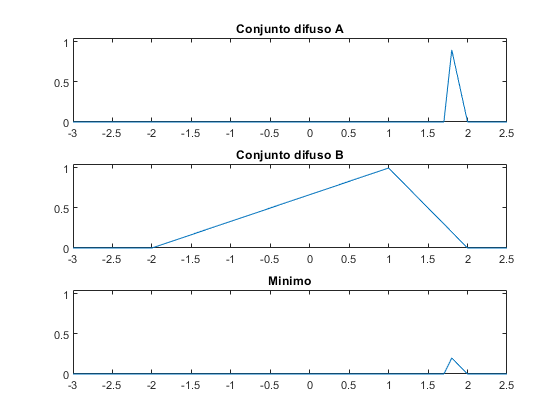

minimo =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.2000    0.1000


dominio = -3:0.1:2.5;
rangoA = [1.7 1.778 2];
rangoB = [-2 1 2];

minimo = problema5(dominio, rangoA, rangoB, 'Minimo')

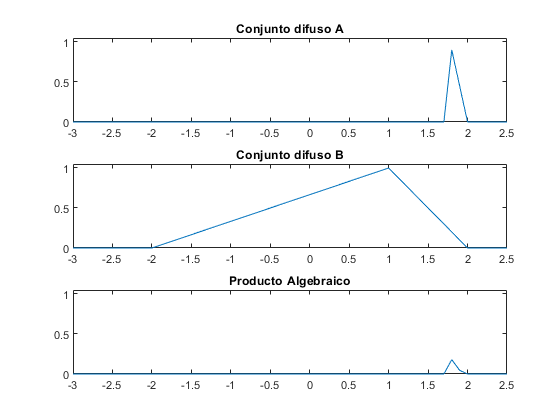

productoAlgebraico =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.1802    0.0450


productoAlgebraico = problema5(dominio, rangoA, rangoB, 'ProductoAlgebraico')

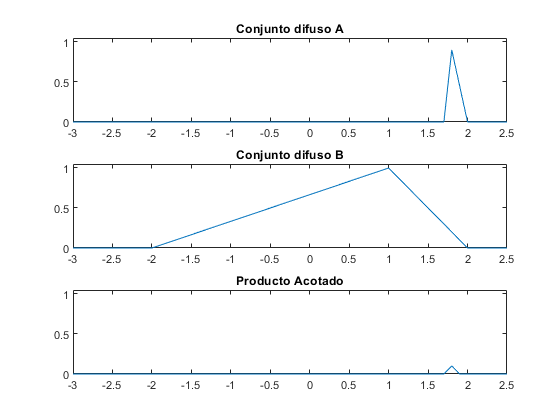

productoAcotado =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.1009         0


productoAcotado = problema5(dominio, rangoA, rangoB, 'ProductoAcotado')

Se puede comprobar informacion en: [https://www.desmos.com/calculator/bw50eicl3o](https://www.desmos.com/calculator/bw50eicl3o)

Problema 6